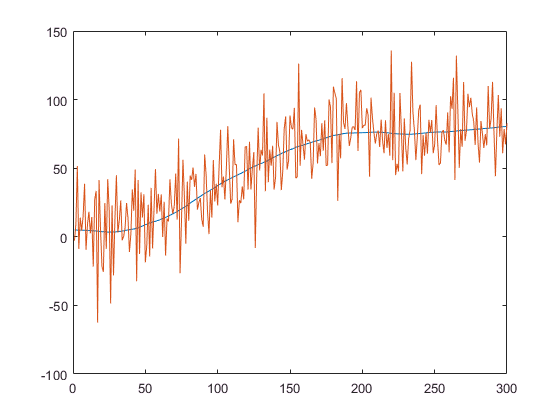

clc; clear; close all;

n=300;
[ X, Z, Acceleration, Noise ] = randomAcceleration( n, sqrt(10), sqrt(500), 5, 0, 0.1);

figure; 
plot(X); hold on;
plot(Z)

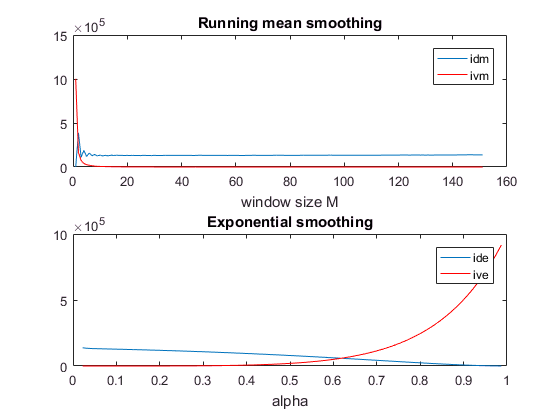

[M, Idm, Ivm, Alpha, Ide, Ive] = bruteforce(Z);

figure; 
subplot(2,1,1);
plot(M,Idm); hold on;
plot(M,Ivm,'red')
title('Running mean smoothing')
legend('idm','ivm')
xlabel('window size M')

subplot(2,1,2);
plot(Alpha,Ide); hold on;
plot(Alpha,Ive,'red')
title('Exponential smoothing')
legend('ide','ive')
xlabel('alpha')